%% SLP SU VOLTI 
% Single‐Layer Perceptron con softmax + cross‐entropy
% Pre‐processing: normalizzazione, centratura e standardizzazione

clear; clc; close all;

%% 1) Parametri di addestramento
epochs        = 500;     % più epoche per convergenza
learning_rate = 0.005;

%% 2) Caricamento dataset
disp('>>> Caricamento dataset...');

>>> Caricamento dataset...


load('dataset/volti_dataset_Yale.mat','A','labels');  % A (m×n), labels
A = double(A) / 255;                                   % [0,1]
[m, n] = size(A);                                      % m = n_pixel, n = n_samples

%% 3) Pre‐processing: centratura + standardizzazione
% Calcolo mean e std su ogni pixel (sulle n immagini)
mean_face = mean(A, 2);                                % [m×1]
std_face  = std(A, 0, 2) + 1e-6;                       % [m×1] (+eps to avoid div0)
A_proc    = (A - mean_face) ./ std_face;               % [m×n] centrato e scalato

%% 4) Prepara X = [n_samples × input_dim] e y
X           = A_proc';      % [n × m]
y           = labels(:);    % [n × 1] vettore colonna
num_classes = max(y);

%% 5) Suddivisione train/test (7 immagini per soggetto per train)
train_idx = [];
test_idx  = [];
for s = 1:num_classes
    idx = find(y == s);
    idx = idx(randperm(numel(idx)));
    train_idx = [train_idx; idx(1:7)];
    test_idx  = [test_idx; idx(8:end)];
end

X_train = X(train_idx, :);   % [n_train × m]
X_test  = X(test_idx,  :);   % [n_test  × m]
y_train = y(train_idx);      % [n_train × 1]
y_test  = y(test_idx);       % [n_test  × 1]

n_train   = size(X_train,1);
n_test    = size(X_test,1);
input_dim = m;

%% 6) One‐hot encoding per softmax‐SLP
Y_train = zeros(num_classes, n_train);
for i = 1:n_train
    Y_train(y_train(i), i) = 1;
end

%% 7) Inizializzazione pesi e bias SLP
rng(0);  % per riproducibilità
W = 0.01 * randn(num_classes, input_dim);  % [C × m]
b = zeros(num_classes, 1);                 % [C × 1]
loss_history = zeros(epochs,1);

%% 8) Training con Gradient Descent (full‐batch)
disp('>>> Addestramento SLP...');

>>> Addestramento SLP (this may take a moment)...


tic;
for ep = 1:epochs
    % Forward
    Z      = W * X_train' + b;             % [C × n_train]
    Z      = Z - max(Z, [], 1);            % stabilità numerica
    expZ   = exp(Z);
    A_soft = expZ ./ sum(expZ, 1);         % [C × n_train]

    % Loss: cross‐entropy media
    loss_history(ep) = -sum(log(A_soft(Y_train==1))) / n_train;

    % Backward
    dZ = (A_soft - Y_train) / n_train;      % [C × n_train]
    dW = dZ * X_train;                     % [C × m]
    db = sum(dZ, 2);                       % [C × 1]

    % Update
    W = W - learning_rate * dW;
    b = b - learning_rate * db;
end
t_training = toc;
fprintf('SLP addestrata in %.2f s\n', t_training);

SLP addestrata in 2.54 s



%% 9) Valutazione sul test set
Z_test = W * X_test' + b;                 % [C × n_test]
[~, y_pred] = max(Z_test, [], 1);         % y_pred: [1 × n_test]
y_pred = y_pred';                         % trasposizione → [n_test × 1]

acc = mean(y_pred == y_test) * 100;       % accuracy
fprintf('Accuracy SLP (test set): %.2f%%\n', acc);

Accuracy SLP (test set): 88.33%


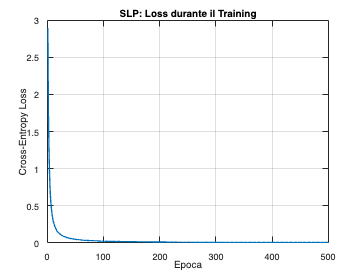


%% 10) Plot della loss
figure('Name','SLP: Cross‐Entropy Loss','NumberTitle','off');
plot(1:epochs, loss_history, 'LineWidth',1.5);
xlabel('Epoca');
ylabel('Cross‐Entropy Loss');
title('SLP: Loss durante il Training');
grid on;